# Synthetic Biology - Modeling genetic circuits

# Code example 1:  Constitutive expression

2024 © Yadira Boada, Alejandro Vignoni

## Modeling gene expression

### Differential equations with Matlab

We will use the `ode45 `command. Its structure is as follows:

%[t,X] = ode45(@(t,x) model(t,x,params),tspan,x0,options);

where

`t `is the independent variable 

`x` is the dependent variable (or vector of variables) 

`model` is the name of the function giving the differential equation, 

`params` contains parameter values 

`tspan` indicates the time over which the solution is to be obtained, 

`x0` represents the initial conditions, 

`options`  the options of the integrator algorithm.

### Constitutive Expression

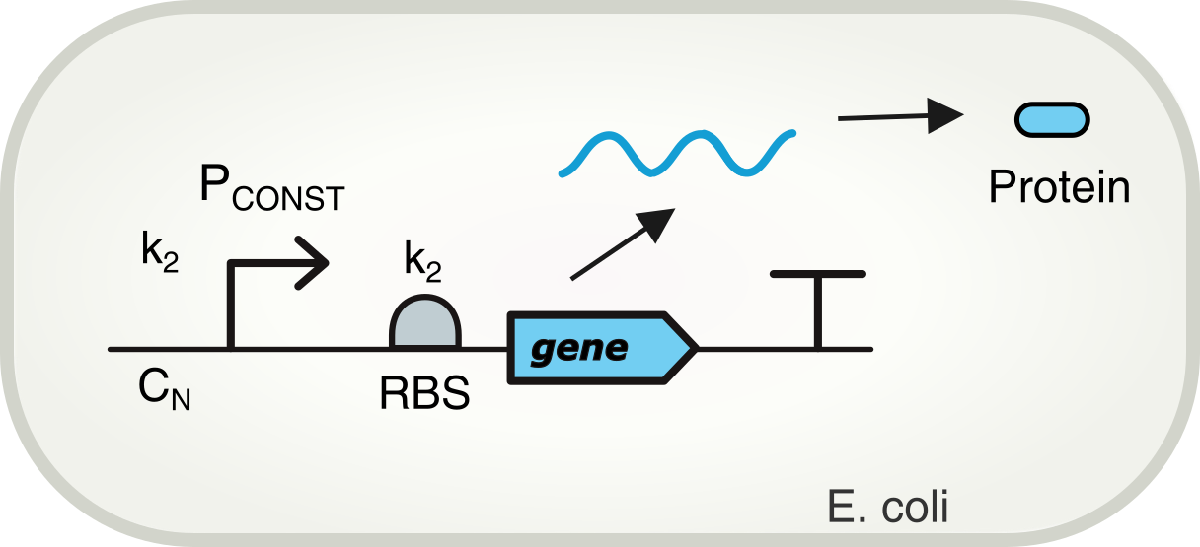

Recall that constitutive expression is given by the mRNA (m) and protein (p) equations:


$$\frac{dm}{dt}=k_1 C_N -d_1m\\
\frac{dp}{dt}=k_2 m -d_2 p$$


See the end of this document for the function definition.

**Main program**

%  Constitutive Gene expression
%   Parameters: structure contains all rates and constants
%   Updated 05/03/2022 by YB, AV

clear
    %Parameters
    p.CN = 17;        % plasmid number  pACYC184 (17 copies/cell)  
    p.d1 = log(2)/3;  % mRNA degradation rate  [1/min]
    p.d2 = 0.02;      % degradation rate [1/min]
    p.k2 = 8.23;      % translation rate  [1/min] 
    p.k1 = 1.19;      % transcription rate [1/min] 
    

tfin = 60*3;   %simulation final time (en minutos, dado por las tasas)
step = 0.1;    %simulation step
tspan = 0:step:tfin-step; 

%options for ode function
opti = odeset('AbsTol',1e-8,'RelTol',1e-6);      
Init = [0 0];  %initial conditions

[t0,x0] = ode23t(@(t,x) model_const(t,x,p),tspan, Init, opti);

%convert time to hour
time = t0./60;

Gene = ones(1800,1).*p.CN;

Finally, we plot the solution.

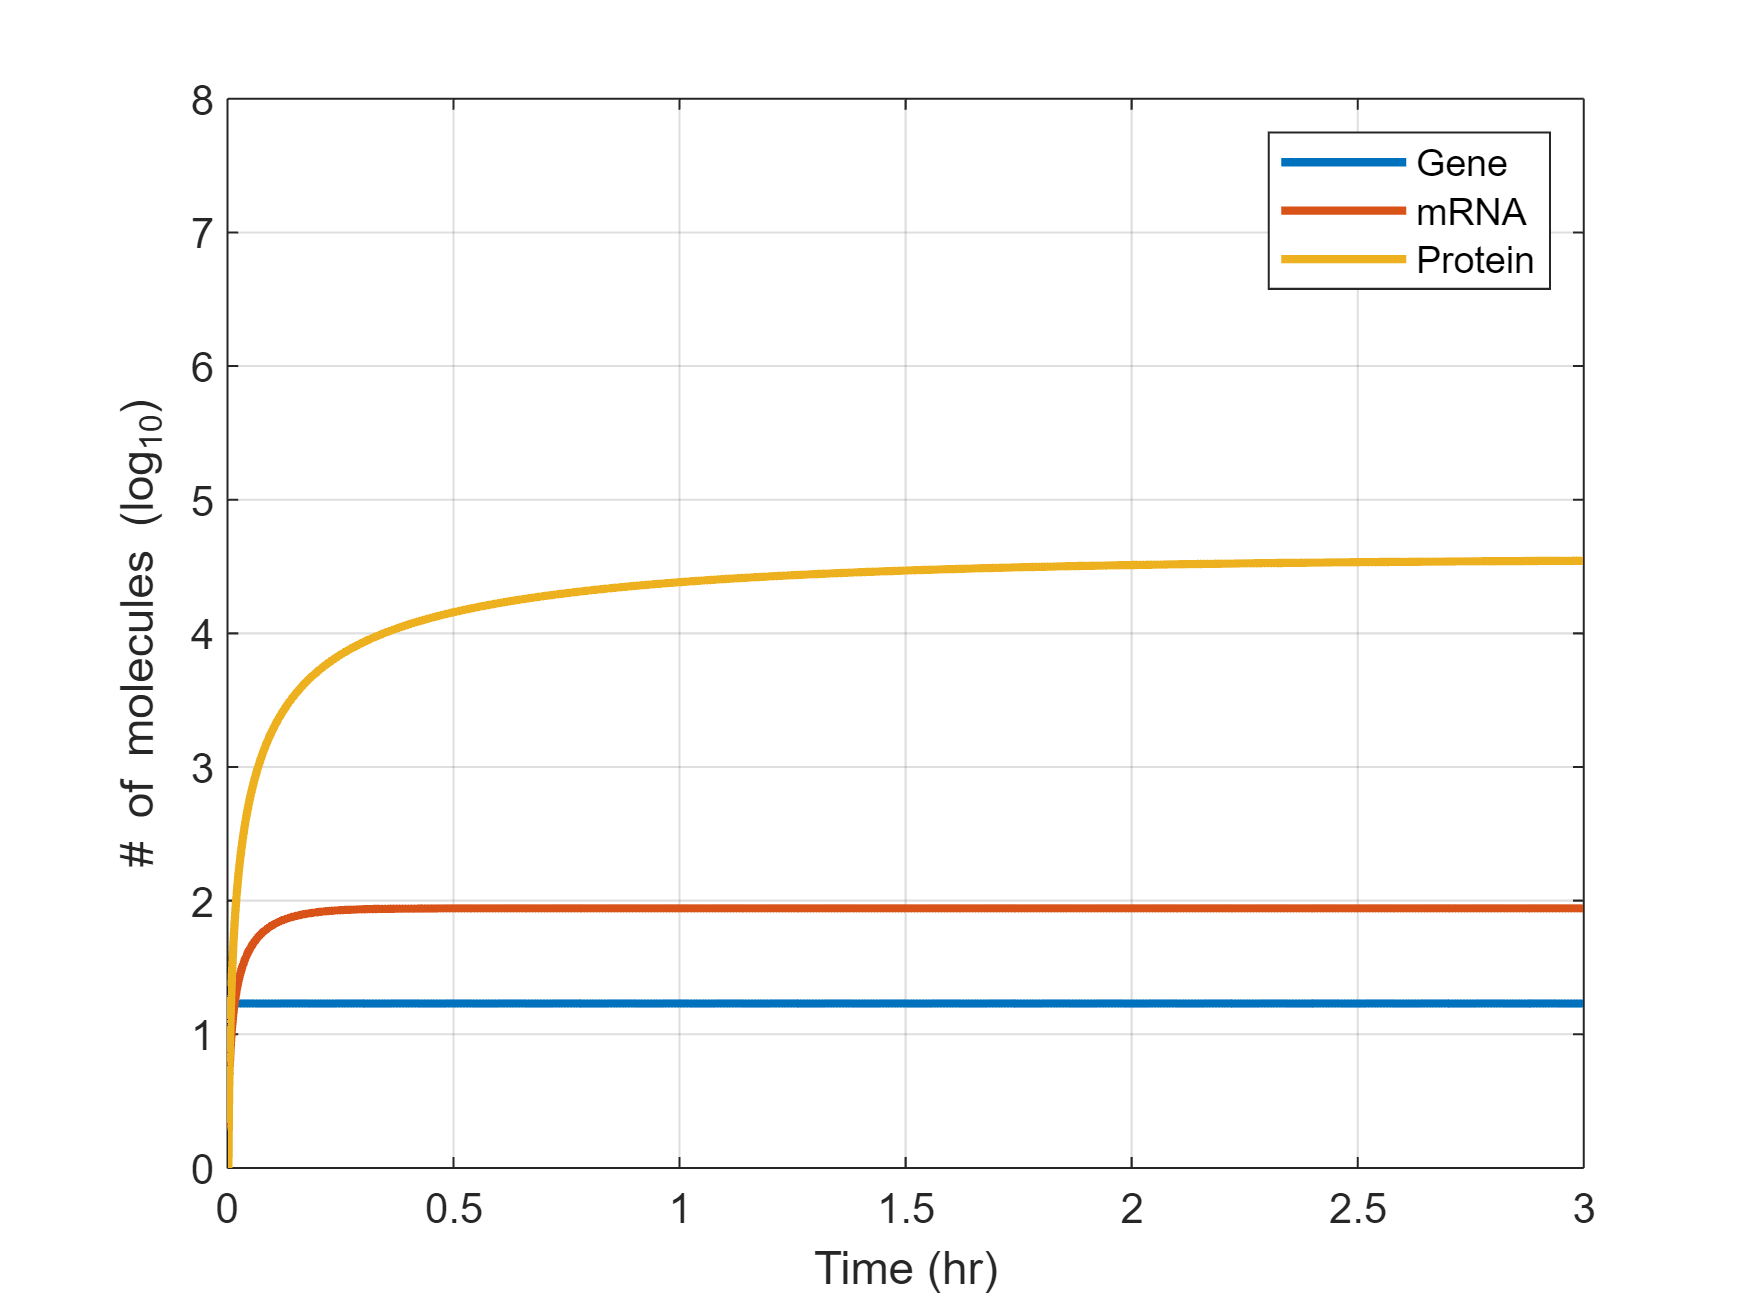

%Plot the simulation results
figure1 = figure('Color',[1 1 1]); 
plot(time,log10(Gene),'LineWidth',2);

hold on;

plot(time,log10(x0(:,1)),'LineWidth',2);

plot(time,log10(x0(:,2)),'LineWidth',2); 
ylabel({'# of molecules (log_{10})'});
xlabel('Time (hr)')
legend('Gene','mRNA','Protein')
ylim([0 8]) 
grid on;

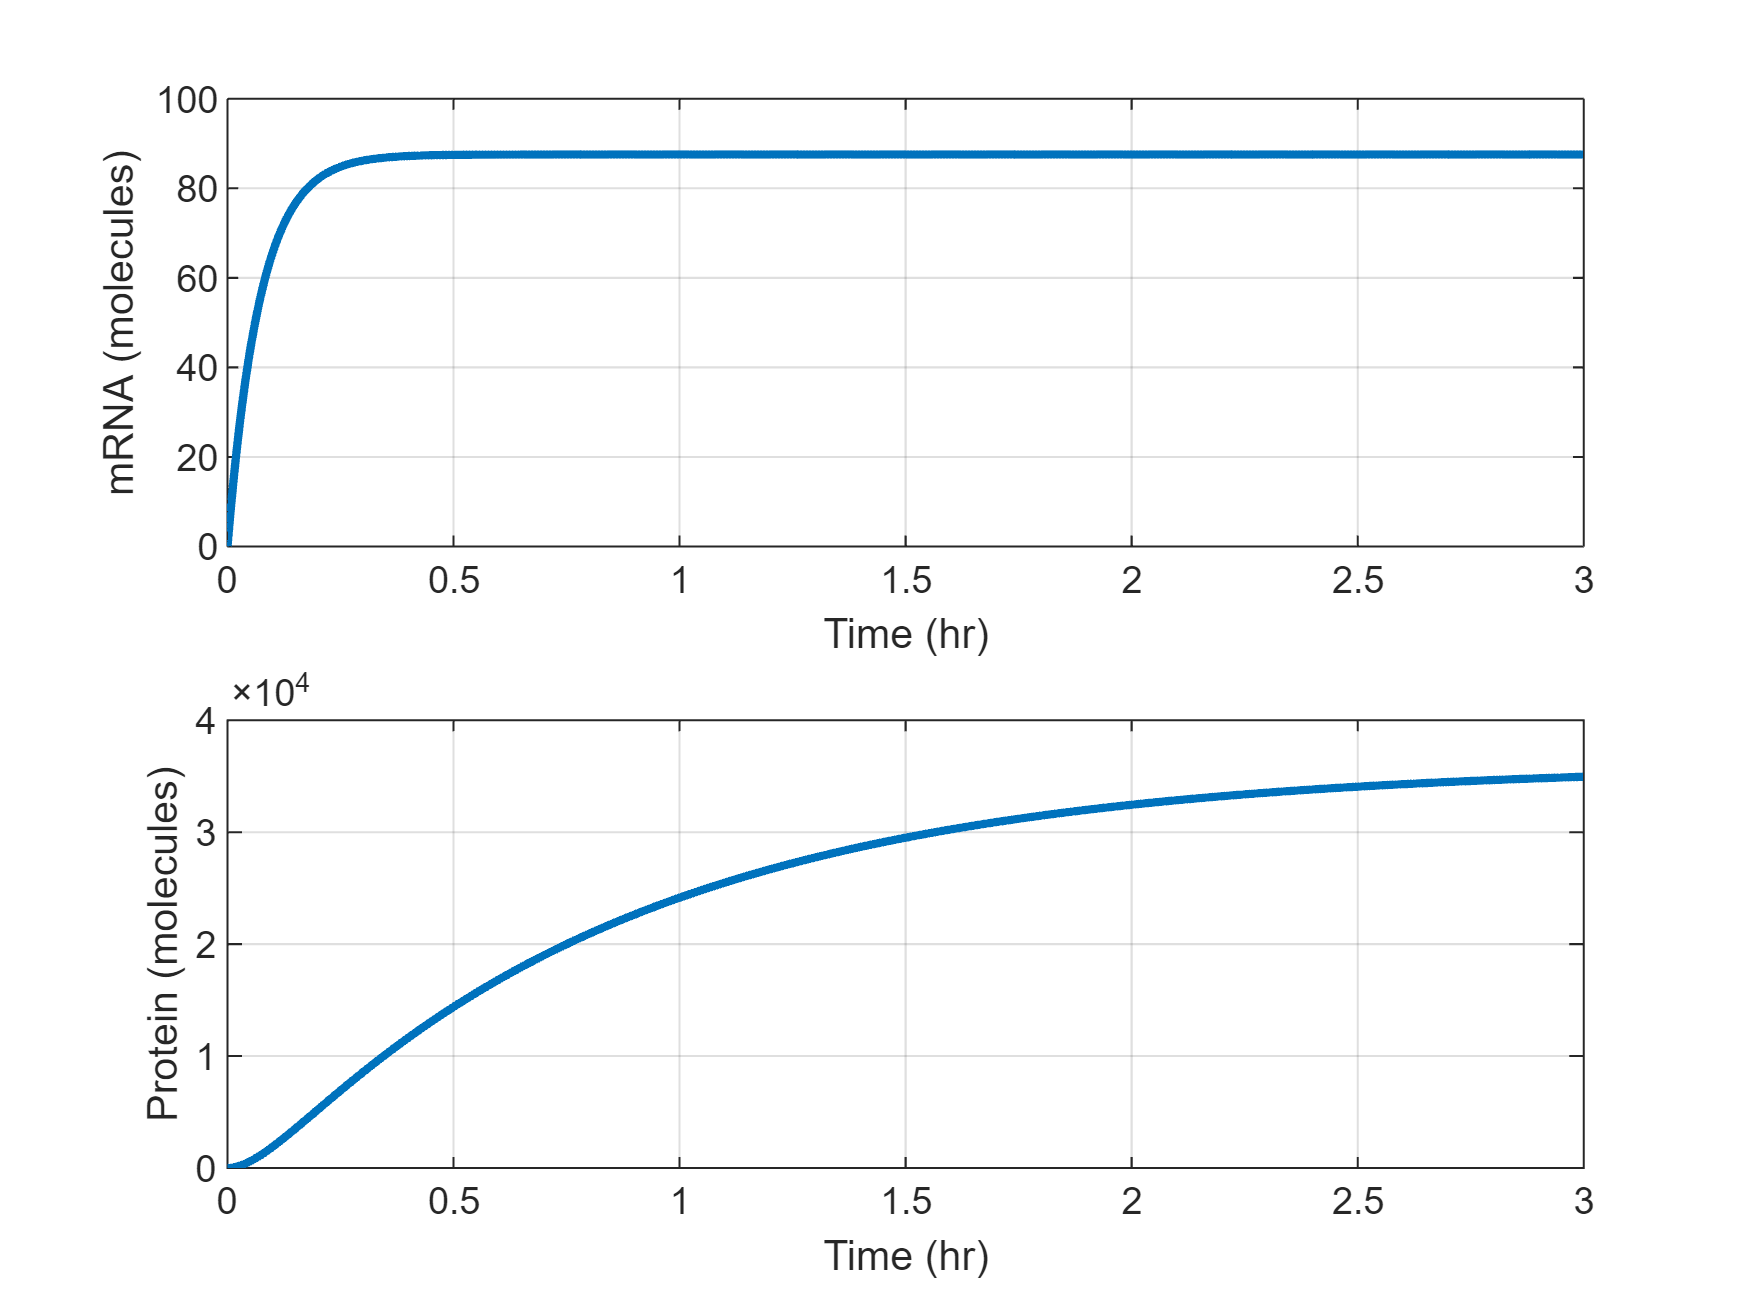


%Plots
 figure1 = figure('Color',[1 1 1]); 
 subplot(211)
 plot(time,(x0(:,1)),'LineWidth',2);
 ylabel('mRNA (molecules)')
 xlabel('Time (hr)')
grid on
subplot(212) 
 plot(time,(x0(:,2)),'LineWidth',2);
 xlabel('Time (hr)')
ylabel('Protein (molecules)')
grid on

function [dxdt] = model_const(t,x,p) %Modelo ODE
%x1 = mRNA
dxdt(1,1) = p.CN*p.k1-p.d1*x(1);
%x2 = Protein
dxdt(2,1) = p.k2*x(1)-p.d2*x(2);
end